# 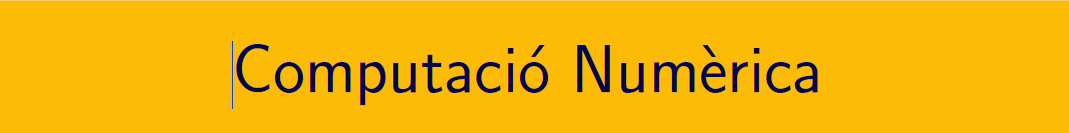

================================================================================

# Pràctica 10. Integració aproximada de funcions i dades (I).

## Introducció

A més a més dels exercicis d'aquest script teniu disponibles exercicis en el document .pdf i en el document **CN_exercicis_tema5_2.pdf**, els podeu trobar en el campus virtual. 

### Bloc 1. MATLAB® - Trapezis

Consulta la documentació i exemples de [trapz](https://es.mathworks.com/help/matlab/ref/trapz.html) i l'exemple de [integració de dades numèriques](https://es.mathworks.com/help/matlab/math/integration-of-numeric-data.html). 

Per al mètode de Simpson, podeu fer ús de l'expressió  $ S(f,h)=\displaystyle\frac{4}{3}T\left(f,\frac{h}{2}\right)-\frac{1}{3}T(f,h)$que relaciona la fórmula dels trapezis i la regla de Simpson. També podeu fer ús dels codis de [codis integració aproximada](http://www.math.mcgill.ca/gantumur/math578f09/?Matlab_files) (revisar el codi)

### Bloc 2.  MATLAB® - Romberg

Podeu fer ús dels codis de Matlab File Exchange, [codis](https://es.mathworks.com/matlabcentral/fileexchange/58286-romberg) 

### Bloc 3.  MATLAB® - Integració adaptativa

La partició de l'interval d'integració es construiex de tal manera que  `abs(q - Q) <= max(AbsTol,RelTol*abs(q)), amb q el valor calculat i Q el valor exacte. Consulteu `[integral](https://www.mathworks.com/help/matlab/ref/integral.html) en la documentació de MATLAB®

Cleve Moler, entre els seus codis del llibre *Numerical computing with Matlab* ens ha preparat una explicació gràfica del procediment. 

%  quadgui(@(x)humps(x),0,1,1.0e-2)
integral(@(x)humps(x),0,1,'RelTol',1e-8,'AbsTol',1e-13)

### Bloc 4.  MATLAB® - Monte Carlo Simulation

Una petita introducció dels mètodes en MATLAB® es pot consultar a l'enllaç següent: [https://es.mathworks.com/discovery/monte-carlo-simulation.html](https://es.mathworks.com/discovery/monte-carlo-simulation.html)

Integració aproximada pel mètode de Montecarlo:  una explicació en el video del professor Craig McNeile a youtube [https://www.youtube.com/watch?v=AaCeUpSFHAk](https://www.youtube.com/watch?v=AaCeUpSFHAk) 

Que s'enten per Monte Carlo Simulation? Una classe del professor John Guttag en el Mit Course: [Introduction to Computational Thinking and Data Science](https://ocw.mit.edu/courses/electrical-engineering-and-computer-science/6-0002-introduction-to-computational-thinking-and-data-science-fall-2016/). Disponible a l'enllaç [https://www.youtube.com/watch?v=OgO1gpXSUzU](https://www.youtube.com/watch?v=OgO1gpXSUzU)

## APRENEM .....

### Exercici 1. Aplicació dades discretes

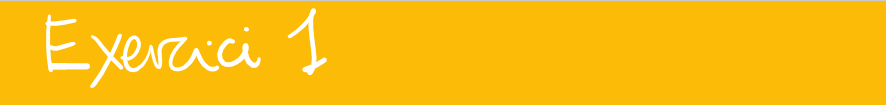

Trobeu la distància que ha recorregut un mòvil a partit de les dades de la següent taula

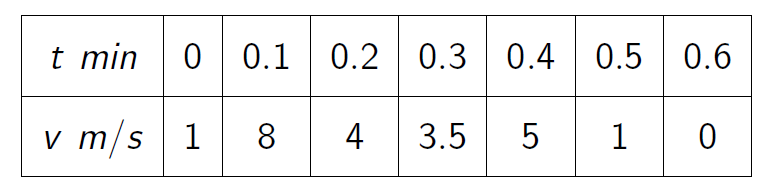

time = linspace(0,0.6,7);
vel = [1 8 4 3.5 5 1 0];

- Representa gràficament les dades de la taula

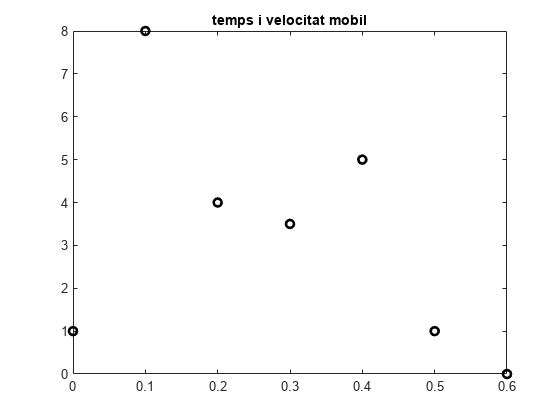

plot(time,vel,'ko', 'LineWidth',2), title('temps i velocitat mobil')
hold off

- Explica l'estratègia i dona el resultat pel mètode del punt mig

timesec = time .* 60;
h= diff(timesec);
puntsmitjos = timesec(1:end-1) + h/2;
puntsmitjos_vel = interp1(timesec, vel, puntsmitjos, 'linear');
aprox = sum(h .* puntsmitjos_vel)

aprox = 132

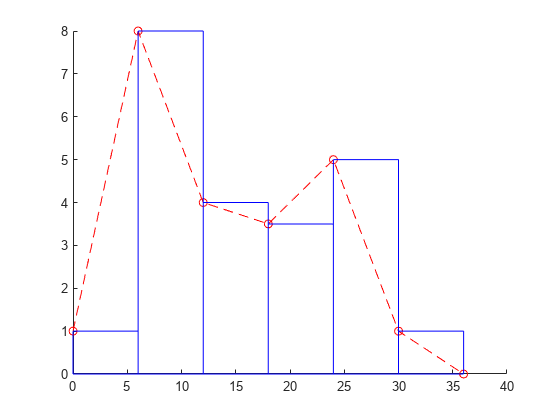

figure
hold on
plot(timesec, vel, 'ro--')
N = length(puntsmitjos_vel);
for i = 1:N
    rectangle('Position', [(i-1)*h(1) 0 h(1) vel(i)], 'EdgeColor', 'b', 'LineWidth', 0.1)
end

hold off

- Explica l'estratègia i dona el resultat pel mètode dels trapezis

aprox = trapz(timesec, vel)

aprox = 132.0000

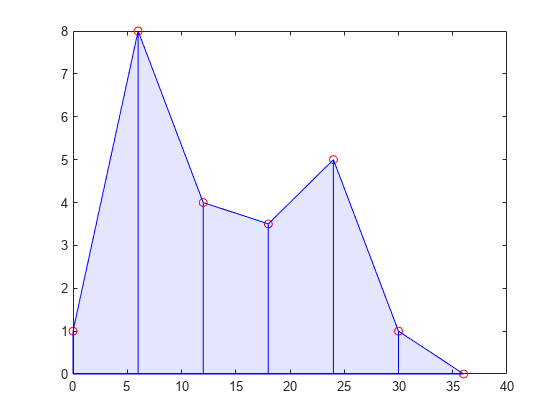

figure;
plot(timesec, vel, 'ro--'); hold on;
for i = 1:6
    x_trap = [timesec(i), timesec(i), timesec(i+1), timesec(i+1)];
    y_trap = [0, vel(i), vel(i+1), 0];
    fill(x_trap, y_trap, 'b', 'FaceAlpha', 0.1, 'EdgeColor', 'b');
end
hold off

- Explica l'estratègia i dona el resultat pel mètode de Simpson

- 
$$ S(f,h)=\displaystyle\frac{4}{3}T\left(f,\frac{h}{2}\right)-\frac{1}{3}T(f,h)$$


h2 = linspace(timesec(1), timesec(7), 2*length(timesec));
yh = interp1(timesec, vel, h2, 'linear');
T2 = trapz(h2, yh)

T2 = 131.3254

Simpson = (4/3)*T2 - (1/3)*aprox

Simpson = 131.1006

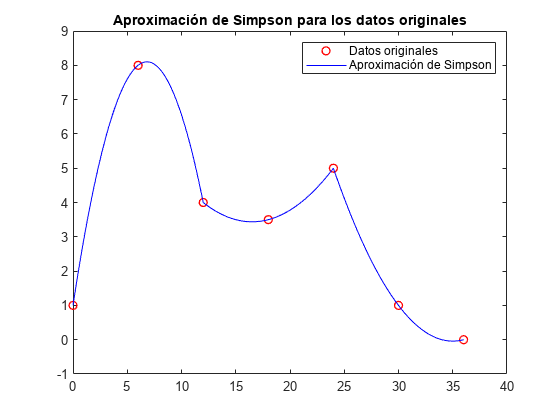

figure
plot(timesec, vel, 'ro', 'LineWidth', 1); % datos originales
hold on
for i = 1:2:length(timesec)-2
    % Para cada conjunto de tres puntos, ajustamos una parábola y la graficamos
    xs = linspace(timesec(i), timesec(i+2), 100); % generamos puntos entre x(i) y x(i+2)
    % Ajustamos la parábola usando polyfit y la evaluamos con polyval
    p = polyfit([timesec(i), timesec(i+1), timesec(i+2)], [vel(i), vel(i+1), vel(i+2)], 2);
    plot(xs, polyval(p, xs), 'b-')
end

legend('Datos originales', 'Aproximación de Simpson')
title('Aproximación de Simpson para los datos originales')
hold off

### Exercici 2. Aplicació per funcions - Fórmules simples

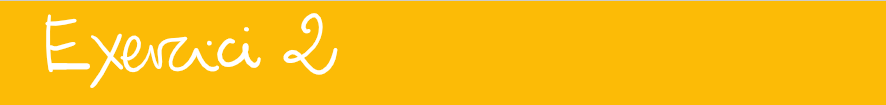

                         
$$\displaystyle \int_{0}^{1} \frac{2}{1+x^2}\, dx\,=\frac{\pi}{2}$$


vc = pi/2

vc = 1.5708

f = @(x)2./(1+x.^2);

- Calculeu, fent ús de la regla del punt mig el valor de $\displaystyle \int_{0}^{1} \frac{2}{1+x^2}\, dx\,$ (simple)

h= 1;
pm = h*f(1/2)

pm = 1.6000

- Calculeu, fent ús de la fórmula del trapezi el valor de $\displaystyle \int_{0}^{1} \frac{2}{1+x^2}\, dx\,$(simple)

t = h/2*(f(0)+f(1))

t = 1.5000

- Calculeu, fent ús de la regla Simpson el valor de $\displaystyle \int_{0}^{1} \frac{2}{1+x^2}\, dx\,$ (simple)

simps = h/6*(f(0)+4*f(0.5)+f(1))

simps = 1.5667

### Exercici 3. Aplicació per funcions - Fórmules compostes

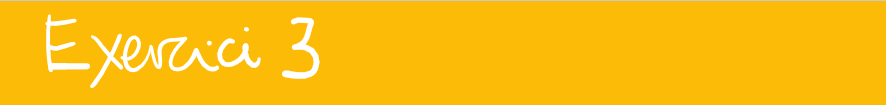

Podeu fer ús dels codis de [codis integració aproximada](http://www.math.mcgill.ca/gantumur/math578f09/?Matlab_files)

                         
$$\displaystyle \int_{0}^{1} \frac{2}{1+x^2}\, dx\,=\frac{\pi}{2}$$


clearvars;
f = @(x)2./(1+x.^2);

- Calculeu, fent ús de la regla del punt mig el valor de $\displaystyle \int_{0}^{1} \frac{2}{1+x^2}\, dx\,$ (4 subintervals)

pm = midp(f, 0, 1, 4)

pm = 1.5734

- Calculeu, fent ús de la fórmula del trapezi el valor de $\displaystyle \int_{0}^{1} \frac{2}{1+x^2}\, dx\,$ (4 subintervals)

tr = trap(f, 0, 1, 4)

tr = 1.5656

- Calculeu, fent ús de la regla Simpson el valor de $\displaystyle \int_{0}^{1} \frac{2}{1+x^2}\, dx\,$ (2 subintervals)

simps = simp(f, 0, 1, 2)

simps = 1.5708

### Exercici 4. Funcions amb singularitats

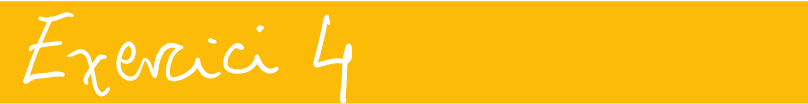

Calculeu $\displaystyle \int_0^{1} \frac{\sin t}{t}\,dt  \approx 0.946083070367 \pm 0.5e\!-\!12$

- Valor correcte

- Regla del punt mig composta. Quants subintervals cal pendre?

- Regla dels trapezis composta. Quants subintervals cal pendre?

### Exercici 5. Mètode de Romberg

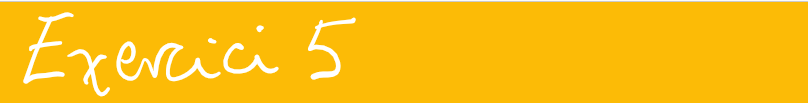

Calculeu mitjançant romberg$\displaystyle \int_0^{0.8} \frac{\sin t}{t}\,dt  \approx 0.772095 \pm 0.5e\!-\!6$

Apliqueu la taula d'extrapolació de romberg (podeu fer ús de [romberg.m](https://es.mathworks.com/matlabcentral/fileexchange/58286-romberg) o un altre, verifiqueu el  vostre codi amb la taula següent)

Resposta 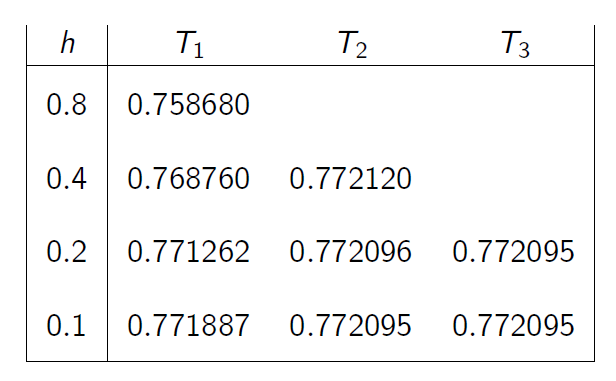

### Exercici 6. Mètode de Montecarlo

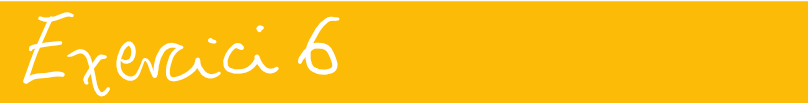

Calculeu els  valors  de    $\displaystyle\int_0^1 x dx = 1/2\,, \quad
\displaystyle\int_0^1 x^2 dx = 1/3\,, \quad
\displaystyle\int_0^4 x dx = 8\,, \quad
\displaystyle\int_{-1}^1 x dx = 1\,.

$

- Tipus I (valor esperat)

- Tipus II (hit or miss)

## AUTOAVALUACIÓ ....

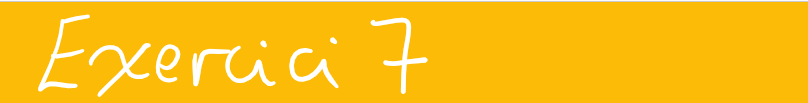

Calculeu la integral $\displaystyle I=\int_{-1}^{1} e^{-x^2}\,dx\,$

- a) Fent ús del mètode dels trapezis per $$h=\displaystyle\frac{1}{2^k},\ \ 0\leq k\leq 5.$

- b) Fent ús del mètode de Simpon per $$h=\displaystyle\frac{1}{2^k},\ \ 0\leq k\leq 5.$

- c) Apliqueu el mètode de Romberg, fent ús dels resultats de l'apartat a) 

- d) Fent ús de mètodes de simulació de MonteCarlo, per mostres de tamany $$M={10^k},\ \ 1\leq k\leq 7.$$

- e)  Doneu els decimals exactes i les xifres significatives del les vostres aproximacions, sabent que  $$\displaystyle\int_0^t e^{-x^2}\,dx\, = \sqrt{\pi}\,erf\left(t\right).$$ Consulteu l'ajuda de Matlab per la funció `erf.`

`Document preparat per M. Àngela Grau Gotés - 3 de maig de 2023`

% Codis de les funcions 